# One-Dimensional Quantum Harmonic Oscillator

In this note we consider 1d time independent Schrödinger equation:


$$\hat H\phi_n(x)=E_n\phi_n(x) \qquad(1)$$


for quantum harmonic oscillator (a particle with a mass $1/2$ in harmonic trapping potential $V(x)=x^2$) with Hamiltonian:


$$\hat H=-\frac{d^2}{d x^2}+x^2. \qquad(2)$$


Below we will derive numerically and analytically exactly energy spectrum: $E_n=2(n+1/2)$, where $n=0,1,2,3,...$ and energy eigen states of equation (1). Exact results will serve as a benchmark to numerical approximation.   

## Numerical Solution

First we study the eigenvalue problem Eq. (1) numerically, introducing 1d grid and using the simple finite difference approximation.

Rmax =70;               % half of the maximal extent of 1d simulation box 
Nr = 10000;                       % number of grid points      
r = linspace(-Rmax, Rmax, Nr)';   % simulation grid 
dr=2*Rmax/Nr;                     % step size
d  = ones(Nr,1);                
Lap_r  = spdiags([d -2*d d],[-1 0 1],Nr,Nr)/dr^2;  % second derivative as Nr x Nr sparse matrix with -2/dr^2 on main (0) diagonal and 1/dr^2 on lower (-1) and upper (1) diagonals  
H =-Lap_r + spdiags(r.^2,0,Nr,Nr); % sparse Hamiltonian matrix
N=8;    % select how many lowest energy eigen states and eigen values to claculate
[V,E]=eigs(H,N,'smallestreal'); % calculate N lowest eigen vectors and values   
diag(E) % first N lowest energy values

ans =     1.0001
    3.0002
    5.0003
    7.0004
    9.0004
   11.0004
   13.0003
   15.0001


Next we plot obtained $N$ lowest energy eigen functions.

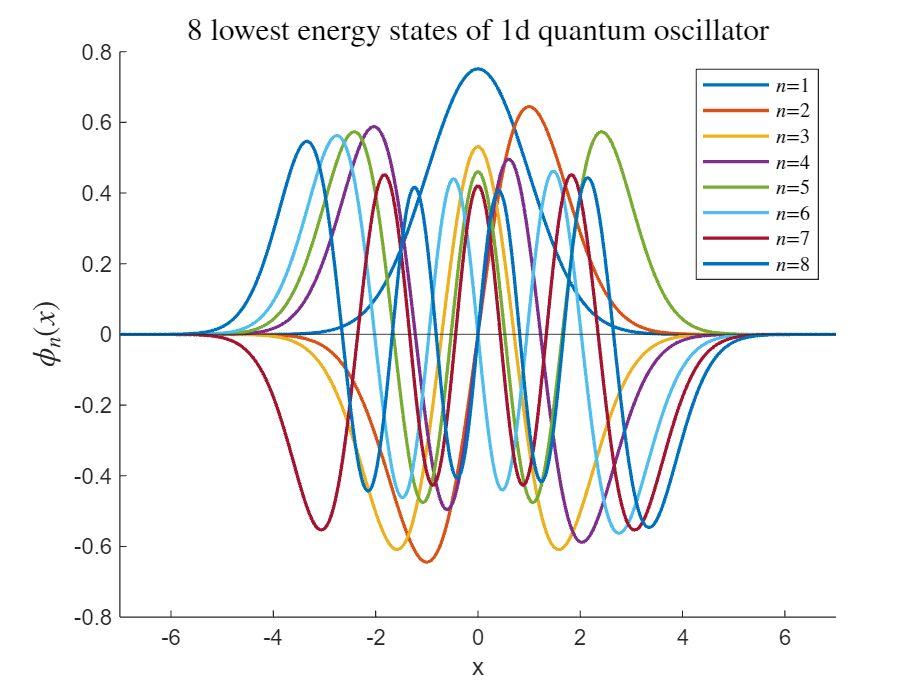

figure
Legend=cell(N,1);
for n=1:N 
    line(r, V(:,n)./sqrt(dr));
    Legend{n}=strcat('$n$=', num2str(n));   
end
legend(Legend,interpreter='Latex');
yline(0, handleVisibility='off'); 
xlim([-7,7]);
xlabel("x");
ylabel("$\phi_n(x)$", interpreter="Latex",fontsize=14)
title(num2str(N) + " lowest energy states of 1d quantum oscillator",interpreter="Latex", fontsize=14 )

## Analytical Solution

 In this section we study the eigenvalue problem Eq. (1) using symbolic computation. We introduce a real number (at this moment $n$ is not necessarily integer, but is any real number to be determined): $n=E_n/2-1/2$ and rewrite Eq. (1) as:


$$\phi_n^{\prime \prime} -x^2\phi_n=-2\left( n+\frac{1}{2} \right) \phi_n. \qquad (3)$$


Next we solve Eq. (3) symbolically.

syms phi_n(x) n 
ode = laplacian(phi_n)-x^2*phi_n+2*(n+1/2)*phi_n==0

$$ode(x) = \varphi_{n}\left(x\right)\,\left(2\,n+1\right)-x^{2}\,\varphi_{n}\left(x\right)+\frac{\partial^{2}}{\partial x^{2}}\varphi_{n}\left(x\right)=0$$

dsolve(ode)

$$ans = \frac{C_{1}\,M_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^{2})}{\sqrt{x}}+\frac{C_{2}\,W_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^{2})}{\sqrt{x}}$$

Hence, generic solution of second order differential Eq. (3) for complex number $x$  is given with the help of Whittaker's M and W functions as


$$\phi_n(x)=C_1\frac{M_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2)}{\sqrt{x}}+C_2\frac{W_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2)}{\sqrt{x}}. \qquad (4)$$


Expression in Eq. (4) for real $x$ is applicable only for $x>0$. Now we require that $\phi_n \to 0$ for $x\to\infty$ (normalizable states), hence we have to let $C_1=0$, unless $n$ is odd positive integer. If $n$ is odd positive integer ($n=1,3,5,...$), then:


$$M_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2)=-\frac{\pi}{\Gamma(-n/2)\Gamma(3/2) }W_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2)$$


and hence for any value of $n$ we can safely put $C_1=0$ in Eq. (4) to obtain the most general physically acceptable (vanishing for $x \to \infty$) solution of  Eq. (3) for $x\ge 0$ as:

 
$$\phi_n(x)=C_2\frac{W_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2)}{\sqrt{x}}. \qquad (5)$$


Expression in Eq. (5) for real $x$ is applicable only for non-negative values of $x$. Whittaker's W function has a regular singularity point at $x=0$ and to extend Eq. (5)  to the region $x<0$, where $\sqrt{x}=i\sqrt{-x}$, we have to use the [following property of the Whittaker's W function](https://dlmf.nist.gov/13.14), with some integer number $m$:


$$W_{\kappa,\mu}(ze^{2m\pi i})  =   \frac{(-1)^{m+1} 2\pi i \sin(2\pi \mu m)}{ \Gamma(1/2-\mu-\kappa)   \Gamma(1+2\mu) \sin(2\pi \mu)}    M_{\kappa,\mu}(z)+   (-1)^m  e^{-2m\mu \pi i}W_{\kappa,\mu}(z). \qquad(6)$$


Putting in Eq. (6) values

- 
$$m=1$$


- 
$$\kappa=n/2+1/4$$


- 
$$\mu=1/4$$


- 
$$z=x^2$$


we obtain


$$W_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2e^{2\pi i})=     \frac{2\pi i}{\Gamma(-\frac{n}{2}) \Gamma(\frac{3}{2})} M_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2) +iW_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2). \qquad(7)$$


At the end of the script we implement fucntion in right-hand-side of Eq. (5) for all values of real $x$, using Eq. (7) for $x<0$, for any real parameter $n$ and for $C_2=1$. We call it nnps (not necessarily physical solution).

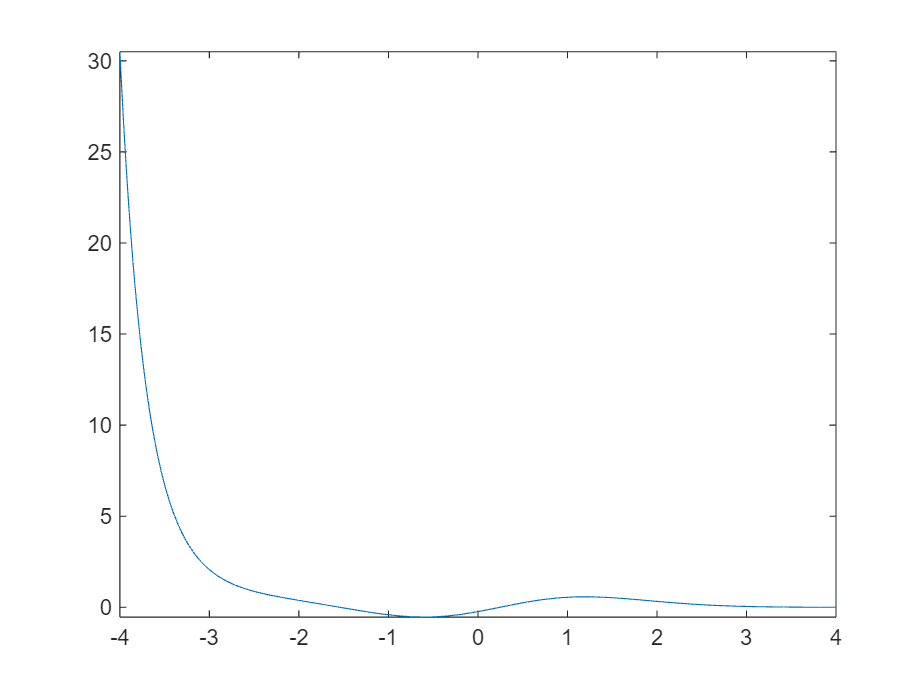

n=1.3;
fplot(nnps(n),[-4,4])

For generic values of $n$, if $n$ is not a nonnegative integer number, then solution given in Eq. (5) is not normalizable, explodes for $x \to -\infty$ (due to the inevitable presence of Whittaker's M function for $x<0$ in Eq. (7)), hence is unphysical. For physically acceptable solutions $n$ **must be nonnegative integer**. It is this step where mathematics imposes quantization of $n=0,1,2,3,...$ and thus quantization of energy levels of quantum 1d harmonic oscillator. 

- **For even nonnegative integer values **of $n$ we have: $\Gamma (1/2-\mu-\kappa)=\Gamma(-n/2)=\infty$, hence for even integer $n\ge 0$ we have from Eq. (7): 


$$W_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2e^{2\pi i})=iW_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2)\qquad (8).$$
  

- **For odd positive integer values **of $n$ the following equatily holds between Whittaker's M and W functions: 


$$\frac{\pi}{\Gamma(-n/2)\Gamma(3/2) }M_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2) =-W_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2), \qquad (9)$$$
 

hence for odd integer $n>0$, using Eq. (7) and Eq. (9), we get: 


$$W_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2e^{2\pi i})=-iW_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2). \qquad(10)$$


Finally, from Eqs. (8) and (10) for any nonnegative integer $n$ we have:


$$W_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2e^{2\pi i})=i(-1)^nW_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2). \qquad(11)$$


Hence 1d quantum harmonic oscillator eigen states in terms of Whittaker's W functions are given by:


$$\phi_n(x)=\begin{cases}  C_2 W_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2)/ \sqrt{x},& \text{for } x\geq 0 \\ C_2(-1)^nW_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2)/ \sqrt{-x}&  \text{for }  x<0 \end{cases} \qquad (12)$$


and corresponding energies are: $E_n=2(n+1/2)$, where $n=0,1,2,3,...$

Choosing $C_2$ so that $\displaystyle \int_{-\infty}^{\infty} \phi^2_n(x) dx=1$, at the end of the script we define symbolic function `HarmonicOscillator(n)=`$\phi_n(x)$ that implements analytically obtained eigen states using Eq. (12) for $n=0,1,2,3,...$ and plot it below (continuous line), comparing with the numerically obtained eigen state (dashed line).

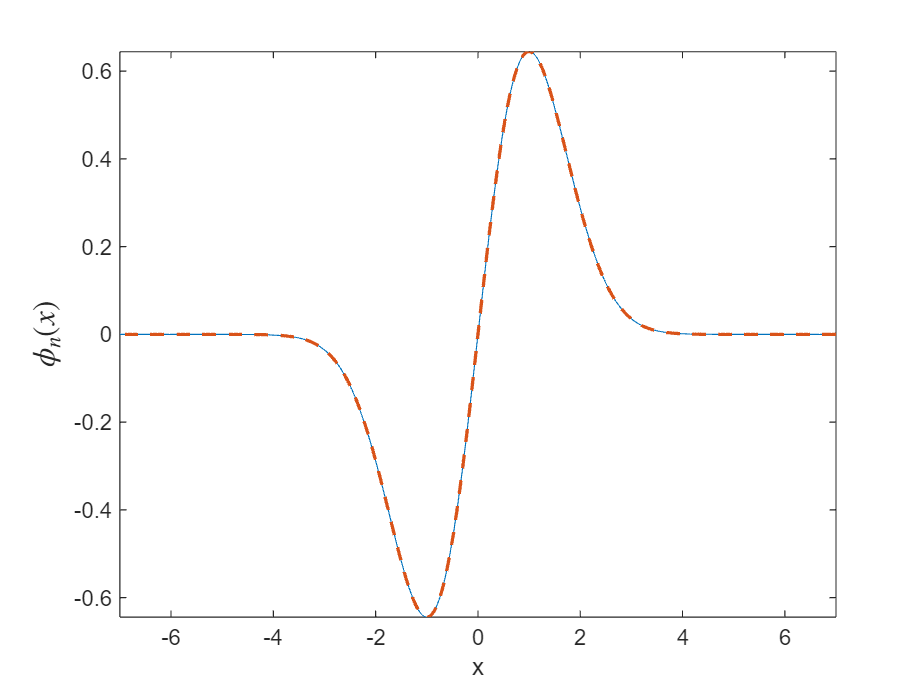

n=1;
fplot(HarmonicOscillator(n))
hold on
plot(r, V(:,n+1)./sqrt(dr),'--');  % compare to numerical solution, may need to change sign in front of V
xlim([-7,7]);
xlabel("x");
ylabel("$\phi_n(x)$", interpreter="Latex",fontsize=14)
hold off

int(HarmonicOscillator(n)^2,-inf,inf) % check normalization

$$ans = 1$$

Finally, we can inspect explicit expressions of normalized eigen functions $\phi_n(x)$.

syms x
assume(x,{'positive','real'})
phi_n(x)=simplify(whittakerW(n/2 + 1/4, 1/4, x^2)/sqrt(x)/sqrt(int(2*whittakerW(n/2 + 1/4, 1/4, x^2)^2/x,0,inf)))

$$phi\_n(x) = \frac{\sqrt{2}\,x\,{\mathrm{e}}^{-\frac{x^{2}}{2}}}{\pi^{1/4}}$$

We can rewite the above normalized wavefunction in terms of [Hermitte-Gaussian](https://en.wikipedia.org/wiki/Hermite_polynomials) functions as:


$$\phi_n(x)=\frac{1}{\sqrt{ 2^n n! \sqrt{\pi}}} e^{-x^2/2}H_n(x). \qquad (13)$$


simplify((2^n*gamma(n+1)*sqrt(sym(pi)))^(-1/2)*exp(-x^2/2)*hermiteH(n,x))

$$ans = \frac{\sqrt{2}\,x\,{\mathrm{e}}^{-\frac{x^{2}}{2}}}{\pi^{1/4}}$$

## Helper Functions

Symbolic function implementing analytical continuation of the right-hand-side of Eq. (5) from $x>0$ to $x<0$ region for $C_2=1$,


$$\phi_n(x)=\begin{cases}  W_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2)/ \sqrt{x},& \text{for } x\geq 0 \\ \frac{2\pi }{\Gamma(-\frac{n}{2}) \Gamma(\frac{3}{2})} M_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2)/ \sqrt{-x} +W_{\frac{n}{2}+\frac{1}{4},\frac{1}{4}}(x^2)/ \sqrt{-x},&  \text{ for }  x<0 \end{cases} \qquad(14)$$


function y = nnps(n) % impementing symbolically function in Eq. (14)
    syms x
    y =(1-heaviside(x))* (2*pi/(gamma(-n/2)*gamma(3/2))*whittakerM(n/2 + 1/4, 1/4, x^2)/sqrt(-x) + whittakerW(n/2 + 1/4, 1/4, x^2)/sqrt(-x))...
      + heaviside(x)*whittakerW(n/2 + 1/4, 1/4, x^2)/sqrt(x);
end


Symbolic function implementing normalized eigen states given in Eq. (12)

function y = HarmonicOscillator(n)
    arguments
        n (1,1) {mustBeInteger,mustBeNonnegative}
    end
    syms x
    y =(1-heaviside(x))* (-1)^n*whittakerW(n/2 + 1/4, 1/4, x^2)/sqrt(-x)+ heaviside(x)*whittakerW(n/2 + 1/4, 1/4, x^2)/sqrt(x);
    y=y/sqrt(int(y^2,-inf,inf));  % implementing unit normalization of particle density
end